# Classification : LDA, SVM

clc; 
clear; 
close all;

**load data**

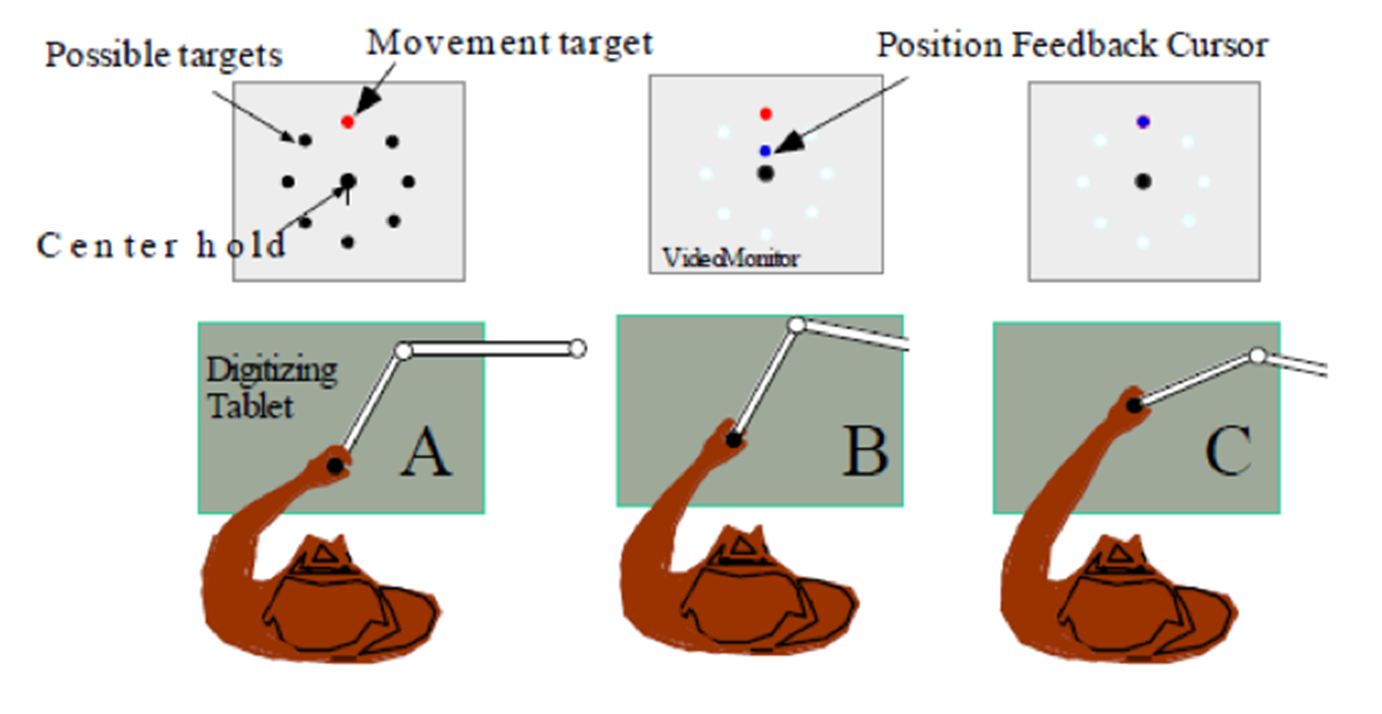

load('data_Flint_2012_e1.mat');
data

data = 다음 필드를 포함한 175×1 struct 배열:
    HandPos
    HandVel
    HandAcc
    Time
    Neuron
    class
    cueOnset
    movementOnset
    movementMax
    movementOffset


**data processing**

% Behavioral output
move_onset = [data.movementOnset];
move_off = [data.movementOffset];

% Directions
dir_class = [data.class];
dir_list = 0:45:315;

The trial time is different from each trial. The behavior data is recorded in each 0.01ms

trial_time = {data.Time};

**Generate Matrix**

n_trial = length(data)

n_trial = 175

`The dataset consists of 196 neurons`

n_neuron = length(data(1).Neuron)

n_neuron = 196

%% Generate Trial x Neuron spike_data matrix
spike_data = cell(n_trial,n_neuron); 
for i = 1:n_trial
    for j = 1:n_neuron
        % Neuron data include the spike timing and LFP data.
        spike_data{i,j} = data(i).Neuron(j).Spike;
    end
end

#### Get Firing rate

Neural firing rate during reaching (between move_onset and move_offset)

FR = zeros(n_trial,n_neuron);
for neuron = 1: n_neuron
    for trial = 1: n_trial
        t_onset = trial_time{trial}(move_onset(trial));
        t_off = trial_time{trial}(move_off(trial));

        num_spikes = sum(spike_data{trial,neuron} > t_onset & spike_data{trial,neuron} < t_off);
        time_bin = t_off - t_onset;

        FR(trial,neuron) = num_spikes./time_bin;
    end
end

% z-score normalization
M = 1e-8;
mean_FR = mean(FR,1);
std_FR = std(FR,[],1);
Z_FR = (FR - mean_FR)./( std_FR + M ); % Prevent the denominator from becoming zero.

Remove neurons less related to hand movement (optional).

idx_mask = mean_FR < 5; % optional value
Z_FR(:,idx_mask) = [];

### **Decoder for Classification**

**Kernels for SVM**

- **Linear** = 'linear'

- **Polynomial** = '`polynomial`'

- **Gaussian** = '`gaussian`'

- **Exponential** = '`polynomial`'

- **Radial-basis function** = '`rbf`'

Also, you can define your own kernel function. For more details, see `help templateSVM`.

- Laplacian

- Hyperbolic/Sigmoid

#### `!!!Fill the blank!!!`

t = templateSVM('KernelFunction','polynomial');

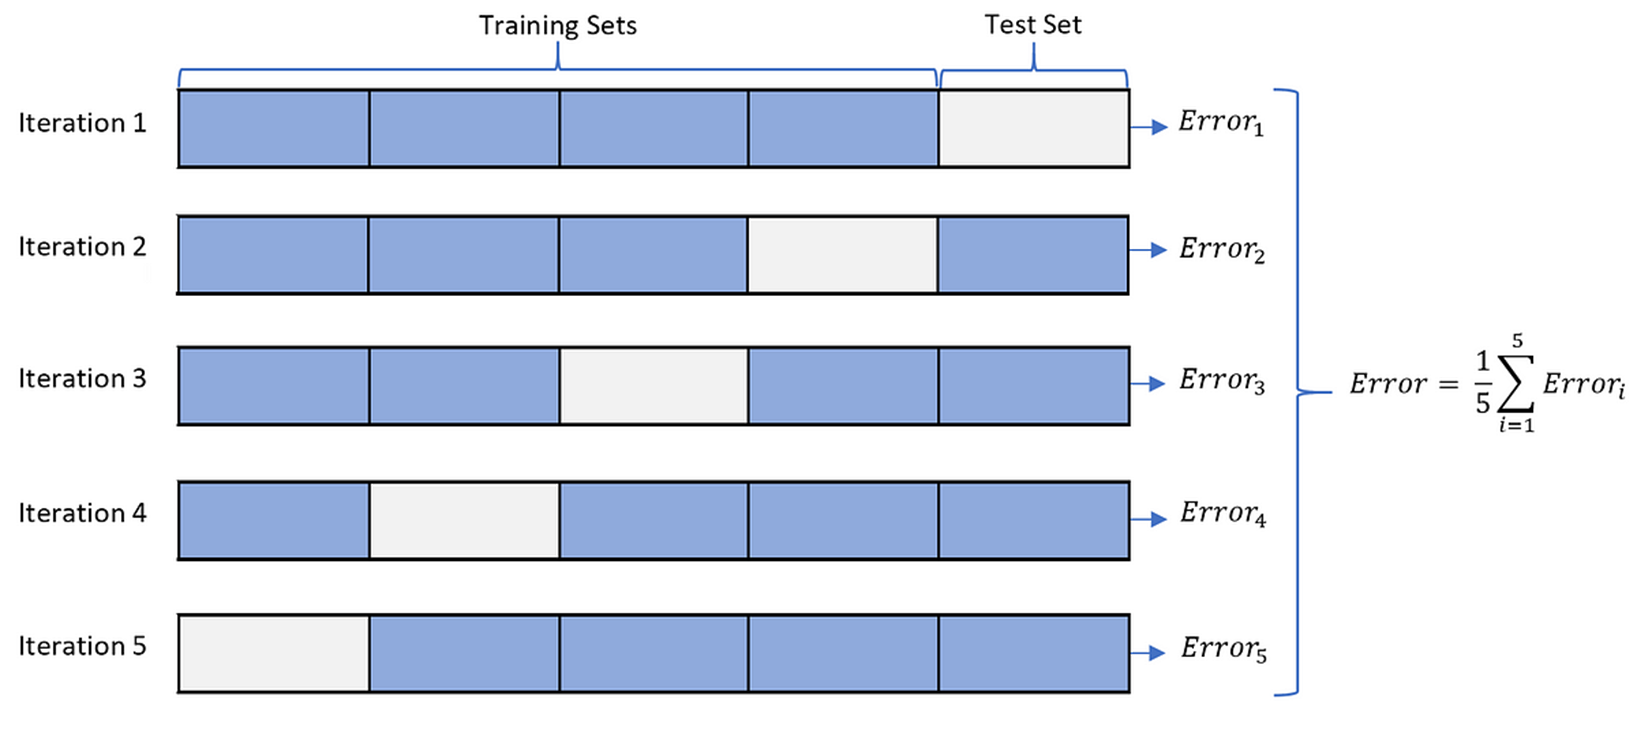

**Used MATLAB function**

- ***cvpartition*** -  define a random partition for the dataset.

- ***training \ test*** - return index for training\testing using cross-validation

- ***fitcecoc*** - fit a multiclass model for Support Vector Machines or other classifiers.

- ***predict*** - return a vector of predicted class labels for the test data based on the trained decoder.

- ***confusionmat \ confusionchart*** - evaluate the performance of a classification model by displaying the relationship between actual and predicted labels in a tabular format. This matrix is useful for visually understanding how accurately the model predicts each class.

% Using 10-fold cross-validation
K = 10;
cv = cvpartition(dir_class,'kfold',K);

% Decode the firing rate pattern to predict target direction
M_train = {}; M_test = {};
acc_train = []; acc_test = [];
for fold = 1:K
    % Get training and test index
    idx_train = training(cv, fold);
    idx_test = test(cv, fold);

    % Divide the training and test data using index
    data_train = Z_FR(idx_train,:);
    data_test = Z_FR(idx_test,:);
    lbl_train = dir_class(idx_train);
    lbl_test = dir_class(idx_test);

#### `!!!Fill the blank!!!`

    % Train the classifier
    mdl = fitcecoc(data_train, lbl_train, 'Learners',t);

| 10-fold cross-validated classification accuracy | Test = 97.12 % | Train = 100.00 % |


    % mdl = fitcdiscr(data_train,lbl_train);

    % Predict the label
    lbl_predict_train = predict(mdl, data_train);
    lbl_predict_test = predict(mdl, data_test);

    M_train{fold} = confusionmat(lbl_train, lbl_predict_train);
    M_test{fold} = confusionmat(lbl_test, lbl_predict_test);

    % Get accuracy
    acc_train(fold) = mean(lbl_train(:) == lbl_predict_train(:));
    acc_test(fold) = mean(lbl_test(:) == lbl_predict_test(:));
end

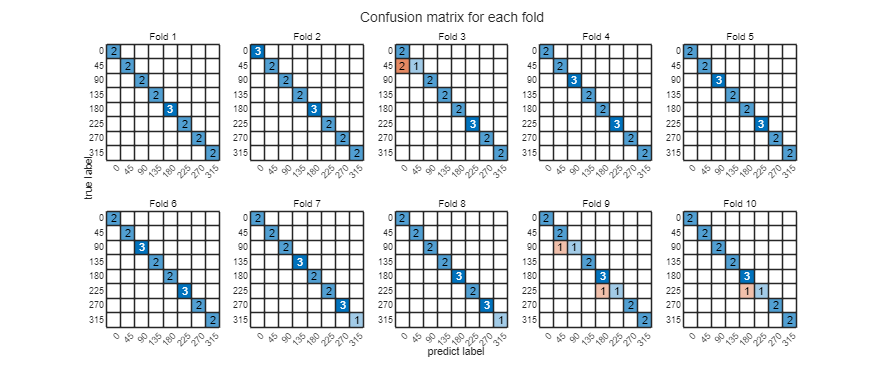

fprintf('| %d-fold cross-validated classification accuracy | Test = %0.2f %% | Train = %0.2f %% |\n', K, 100*mean(acc_test) , 100*mean(acc_train) );

figure('Position',[0 0 1100 460]);
tiledlayout(2,K/2)
for fold = 1: K
    nexttile();
    cm = confusionchart(M_test{fold}, dir_list);
    xlabel(''); ylabel('');   
    title(['Fold ' num2str(fold)])
end
sgtitle('Confusion matrix for each fold')

ax = axes('Visible','off');
ax.XLabel.Visible = 'on';
ax.YLabel.Visible = 'on';
xlabel('predict label', 'FontSize',18); ylabel('true label', 'FontSize',18);